# Cooperative MARL for Weak Control Loops

## Model

mdl = "DistillationWeakMixed";
open_system(mdl);

## Environment

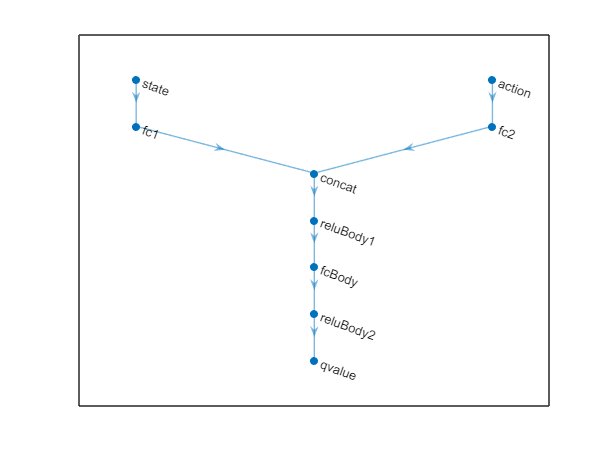

[env,obsInfo,actInfo] = localCreateEnv(mdl);
rng(1);
Ts = 0.1; % Time step
Tf = 200; % End time
agent31 = create31TD3(obsInfo{1}, actInfo{1},Ts);

agent32 = create32TD3(obsInfo{2}, actInfo{2},Ts);

## Training Options

maxepisodes = 100;
maxsteps = ceil(Tf/Ts);
trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups",{[1,2]},...
    "LearningStrategy", "centralized",...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',[0 0]);

## Simulate once for sanity check

simOpts = rlSimulationOptions('MaxSteps',maxsteps);
exp = sim(env,[agent31 agent32],simOpts);
s1 = sum(exp(1).Reward)
s2 = sum(exp(2).Reward)
s1 + s2

## Training Agent

train([agent31 agent32],env,trainOpts);
save('MixedWeakagent1.mat','agent31') 
save('MixedWeakagent2.mat','agent32') 

## Model for cooperative MARL

mdl = "DistillationWeakCoop";
open_system(mdl);

## Environment

[env,obsInfo,actInfo] = localCreateEnvStrong(mdl);
rng(1);
agent31 = create31TD3(obsInfo{1}, actInfo{1},Ts);
agent32 = create32TD3(obsInfo{2}, actInfo{2},Ts);

## Training Options

trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups","auto",...
    "LearningStrategy", "decentralized",...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',[0 0]); %[0 204]

## Simulate once for sanity check

simOpts = rlSimulationOptions('MaxSteps',maxsteps);
exp = sim(env,[agent31 agent32],simOpts);
sum(exp(1).Reward)

ans = -388.6057

sum(exp(2).Reward)

ans = -388.6057

## Training Agent

train([agent31 agent32],env,trainOpts);
save('CoopWeakagent1.mat','agent31') 
save('CoopWeakagent2.mat','agent32') 